# Using the Leaderboard Toolbox

Edit this file directly to add a new player, or by using the addPlayerToFile function.

type players.csv


Name,ID
Michael Cappello,34524
Andrew Newell,631608
Grzegorz Knor,1861624
Evan,3303717
Yaroslav,3354683
PurpleDiab,5960633
cokakola,7164325
Jakub Mrowka,8171411
Erik Luiten,8960155
Jiahang Li,11433059


player_file = which("players.csv");
players = readtable(player_file,"TextType","string")

players = 10×2 table
           Name               ID    
    __________________    __________

    "Michael Cappello"         34524
    "Andrew Newell"       6.3161e+05
    "Grzegorz Knor"       1.8616e+06
    "Evan"                3.3037e+06
    "Yaroslav"            3.3547e+06
    "PurpleDiab"          5.9606e+06
    "cokakola"            7.1643e+06
    "Jakub Mrowka"        8.1714e+06
    "Erik Luiten"         8.9602e+06
    "Jiahang Li"          1.1433e+07


## Make the HTML Leaderboard File

f = 'leaderboard.html';
makeLeaderboard(f,currentTable.Id)

Undefined variable "currentTable" or class "currentTable.Id".

## Collect the Data

Run this at a regular interval to get the latest scores.

f = 'scores.csv';
scoreTable = gatherScoreData(f,players.ID)

scoreTable = 20×3 timetable
            Time                Id        Score    Badges
    ____________________    __________    _____    ______

    27-Mar-2019 12:54:26         34524    8340       10  
    27-Mar-2019 12:54:26    6.3161e+05    8720       22  
    27-Mar-2019 12:54:26    1.8616e+06    9090       15  
    27-Mar-2019 12:54:26    3.3037e+06    8750        9  
    27-Mar-2019 12:54:26    3.3547e+06    8425       15  
    27-Mar-2019 12:54:26    5.9606e+06    9000       10  
    27-Mar-2019 12:54:26    7.1643e+06    9780       39  
    27-Mar-2019 12:54:26    8.1714e+06    9545       12  
    27-Mar-2019 12:54:26    8.9602e+06    8755       10  
    27-Mar-2019 12:54:26   

## Make a Leaderboard Table

t1 = datetime('now')
currentTable = leaderTableAtTime(players, scoreTable, t1)

t1 = datetime
   02-Apr-2019 15:54:18


## Plot Player Scores Over Time

id = currentTable.Id;

currentTable = 10×4 table
           Name               Id        Score    Badges
    __________________    __________    _____    ______

    "cokakola"            7.1643e+06    9780       39  
    "Jakub Mrowka"        8.1714e+06    9545       12  
    "Jiahang Li"          1.1433e+07    9100       11  
    "Grzegorz Knor"       1.8616e+06    9090       15  
    "PurpleDiab"          5.9606e+06    9000       10  
    "Erik Luiten"         8.9602e+06    8755       10  
    "Evan"                3.3037e+06    8750        9  
    "Andrew Newell"       6.3161e+05    8720       22  
    "Yaroslav"            3.3547e+06    8425       15  
    "Michael Cappello"         34524    8340       10  


clf
hold all
for i = 1:length(id)
    ix = find(scoreTable.Id == id(i));
    plot(scoreTable.Time(ix),scoreTable.Score(ix),'.-', ...
        'MarkerSize',18)
end
hold off
d =  max(scoreTable.Time);
d.Format = "dd MMM uuuu";
title(sprintf('Last Updated On %s',d))
legend(currentTable.Name,'Location',"eastoutside")

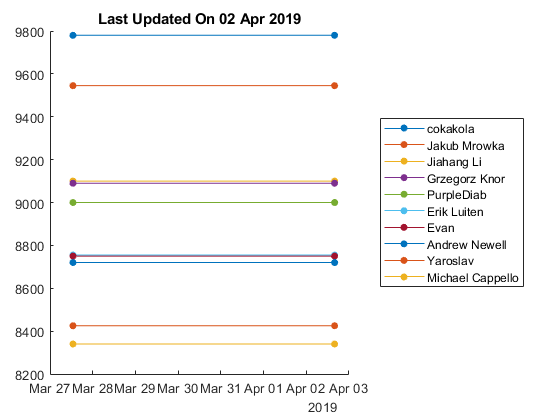

[scoreMatrix,t,playerNames] = makeScoreMatrix(scoreTable, players);

plot(t,scoreMatrix,'.-','MarkerSize',12)

legend(playerNames,"Location","eastoutside")

plot(scoreMatrix,'.-','MarkerSize',12)
legend(playerNames,"Location","eastoutside")

makeRankPlot(scoreMatrix, t, playerNames);

## Changes in the last 30 Days

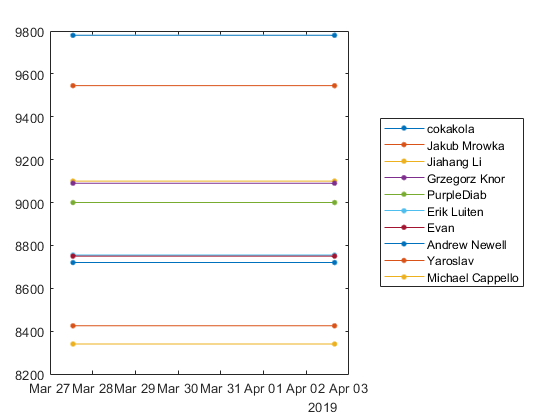

t2 = datetime;

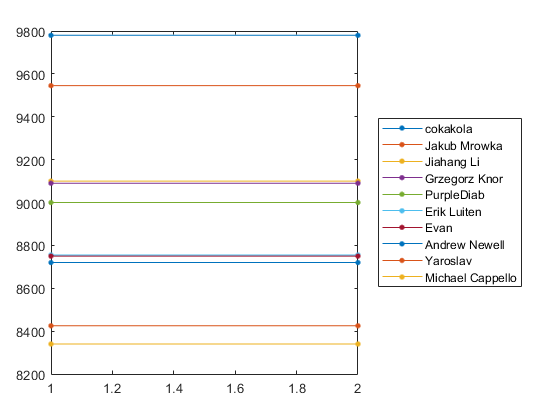

nDays = 30;
t1 = t2 - days(nDays)
dMinus30Table = leaderTableAtTime(players,scoreTable,t1);

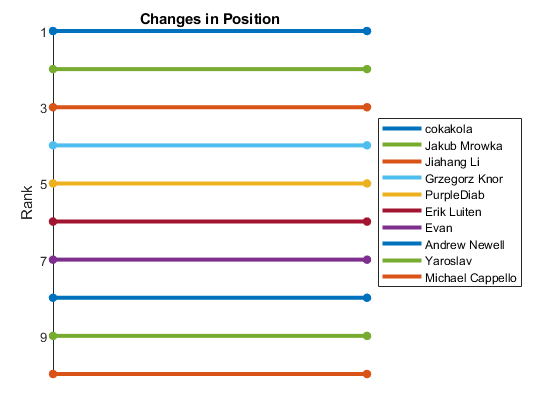

currentTable = leaderTableAtTime(players,scoreTable,t2);


Rank = zeros(height(players),1);
RankChange = zeros(size(Rank));
ScoreChange = zeros(size(Rank));

for i = 1:height(currentTable)
    Rank(i) = i;

t1 = datetime
   03-Mar-2019 15:54:32


    ixOld = find(dMinus30Table.Id==currentTable.Id(i));
    if isempty(ixOld)
        RankChange(i) = NaN;
        ScoreChange(i) = currentTable.Score(i);
    else
        RankChange(i) = ixOld - Rank(i);
        ScoreChange(i) = currentTable.Score(i) - dMinus30Table.Score(ixOld);
    end
end

currentTable = [currentTable table(Rank,RankChange,ScoreChange)]

fprintf('Changes in the Last %d Days\n\n',nDays);

currentTable = 10×7 table
           Name               Id        Score    Badges    Rank    RankChange    ScoreChange
    __________________    __________    _____    ______    ____    __________    ___________

    "cokakola"            7.1643e+06    9780       39        1        NaN           9780    
    "Jakub Mrowka"        8.1714e+06    9545       12        2        NaN           9545    
    "Jiahang Li"          1.1433e+07    9100       11        3        NaN           9100    
    "Grzegorz Knor"       1.8616e+06    9090       15        4        NaN           9090    
    "PurpleDiab"          5.9606e+06    9000       10        5        NaN           9000    
    "Erik Luiten"         8.9602e+06    8755       10        6        NaN           


for i = 1:height(currentTable)

Changes in the Last 30 Days



    if isnan(currentTable.RankChange(i))
        rankStr = "New player this period";
    elseif currentTable.RankChange(i)<0
        rankStr = sprintf("Rank decreased by %d",abs(currentTable.RankChange(i)));
    elseif currentTable.RankChange(i)==0
        rankStr = "Rank unchanged"
    else
        rankStr = sprintf("Rank improved by %d",currentTable.RankChange(i));
    end
    fprintf("%2d. %20s: %4d (%s)\n", ...
        i,currentTable.Name(i), currentTable.Score(i), rankStr);
end

 1.             cokakola: 9780 (New player this period)
 2.         Jakub Mrowka: 9545 (New player this period)
 3.           Jiahang Li: 9100 (New player this period)
 4.        Grzegorz Knor: 9090 (New player this period)
 5.           PurpleDiab: 9000 (New player this period)
 6.          Erik Luiten: 8755 (New player this period)
 7.                 Evan: 8750 (New player this period)
 8.        Andrew Newell: 8720 (New player this period)
 9.             Yaroslav: 8425 (New player this period)
10.     Michael Cappello: 8340 (New player this period)
